# Workbook: Dim Flash Analysis

In this document we will use the data from `fixedFlashResponses.csv` to produce a cursory analysis of responses to a fixed intensity flash. For the purposes of our analysis, we will assume an arbitrary intensity as this analysis is meant to highlight the operations required to generate the analysis.

First, we will import the data to a `table` object. We do this because the `csv` file contains a header row with variable names. We can automatically detect header rows using the `readtable()` function.

% Do not edit
% Read data from csv
data = readtable("./lib/data/fixedFlashResponses.csv");

## Inspect Data Table

If we inspect the data table properties, we can see that there are 3 columns (Variables) named `Index`, `Time`, and `Responses`. 

data.Properties

ans =   TableProperties with properties:
             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Index'  'Time'  'Responses'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.

We can get a summary of the variables using `summary()`, which will tell us the range and number of elements in each table variable.

summary(data)

Variables:
    Index: 1431000×1 double
        Values:
            Min            1  
            Median      45.5  
            Max           90  
    Time: 1431000×1 double
        Values:
            Min              0
            Median    71.54995
            Max       143.0999
    Responses: 1431000×1 double
        Values:
            Min        -1.26104800624315
            Median    0.0286825238439663
            Max         4.08832508283124


Finally, we can inspect the first 10 rows of the data table using the `head()` function.

head(data,10)

ans = 10×3 table
    Index     Time          Responses     
    _____    ______    ___________________
      1           0    -0.0157724262854473
      1      0.0001    -0.0184011553137154
      1      0.0002     -0.021045897750051
      1      0.0003    -0.0237044255832657
      1      0.0004    -0.0263744538412264
      1      0.0005    -0.0290536421097486
      1      0.0006    -0.0317395961692713
      1      0.0007    -0.0344298697513885
      1      0.0008    -0.0371219664169532
      1      0.0009    -0.0398133415571109

## Inspect Data

Some information about the data are missing, such as, what `Index` means and what units correspond to the `Time` and `Responses` variables. For our purposes, the relavant meta-data is listed below, but this is a major drawback when using text-delimited (like `csv`, `tsv`, `txt`) file extensions.

From these data, let's create some variables for use in our analysis.

FlashIntensity = 1.31;
FlashOffset = 0.2;
CollectingArea = 0.26;
SamplingRate = 10000;
Units = struct( ...
  'Time', 'sec', ...
  'Responses', 'pA', ...
  'FlashIntensity', 'R*/rod', ...
  'CollectingArea', 'um^2', ...
  'SamplingRate', 'Hz'...
  );

Further, the following image shows a detailed view of the data. Each flash trial is color coded. The inset is an expanded view of the area outlined in the black rectangle (the first 10 trials).

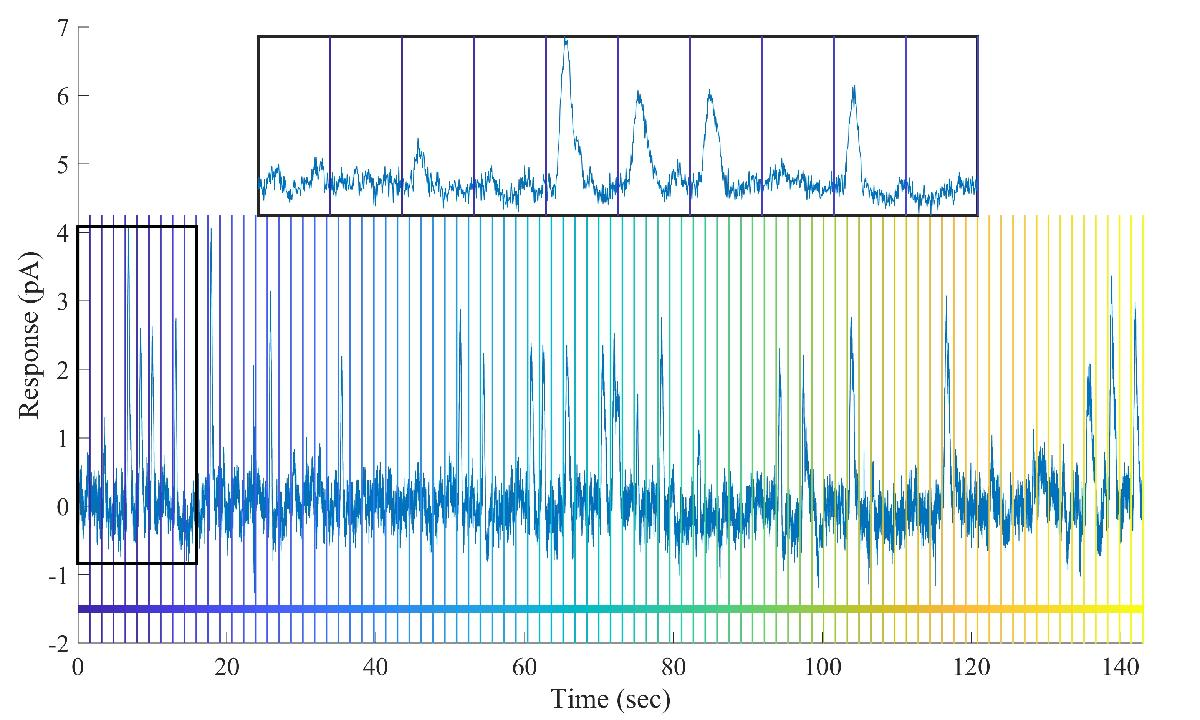

### Visualizing Data

It is always best to start with a basic visualization of the data. We can simply plot the data.

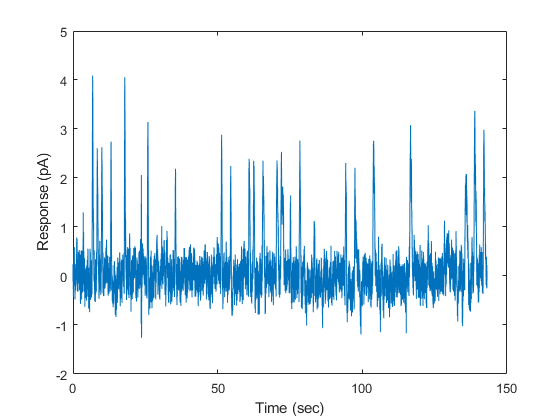

% plot the Time and Responses variables
plot(data.Time,data.Responses);
% annotate the axes
ylabel("Response (pA)");
xlabel("Time (sec)");

Note: To gain more control over the aesthetics of the figure, see the formatting and annotation documentation [here](https://www.mathworks.com/help/matlab/formatting-and-annotation.html).

### Manipulate Data

We can see that we have a single trace of response trials. The data table contains an `Index` variable that allows us to group the responses based on their trial number. From our summary above, we can see that `Index` has a domain of `[1,90]`. We might assume that the domain is covered as a range of `1:90`, but a better approach would be to avoid making any assumptions. We can simply check the range by determining the unique values of the variable.

ids = unique(data.Index,'stable');
ids

ids =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


Note: the argument `'stable'` prevents `unique()` from sorting the output.

There are a number of ways we can group the data now that we have a vector of response IDs. I find that the most efficient and readable approach is to determine the size of the final output and pre-allocate the matrix in which we want to store the responses. Here is my approach.

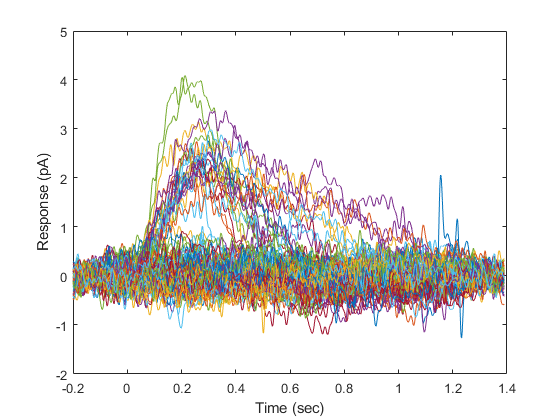

nResp = numel(ids); % number of responses
responseLengths = zeros(nResp,1); % pre-allocate length for each response
for r = 1:nResp
  responseLengths(r) = sum(data.Index == ids(r)); % store length of each response
end

% pre-allocate the grouped responses
groupedResponses = nan(max(responseLengths),nResp);

% collect each response and align by the first element
for r = 1:nResp
  groupedResponses(1:responseLengths(r),r) = data.Responses(data.Index == ids(r));
end

% Create a unified time vector
time = ((1:max(responseLengths)).'-1) ./ SamplingRate;
% adjust the time vector so responses are aligned by flash onset
time = time - FlashOffset;
plot(time,groupedResponses);
% annotate
ylabel(sprintf("Response (%s)",Units.Responses));
xlabel(sprintf("Time (%s)", Units.Time));

Now we have a matrix of responses and a time vector that aligns the repsonses by the onset of the flash trial. 

## Analyze Data

With the data in an aligned matrix, we can now simply preform the statistical analysis to generate the time-dependent mean and variance. At each step, we should investigate the data. 

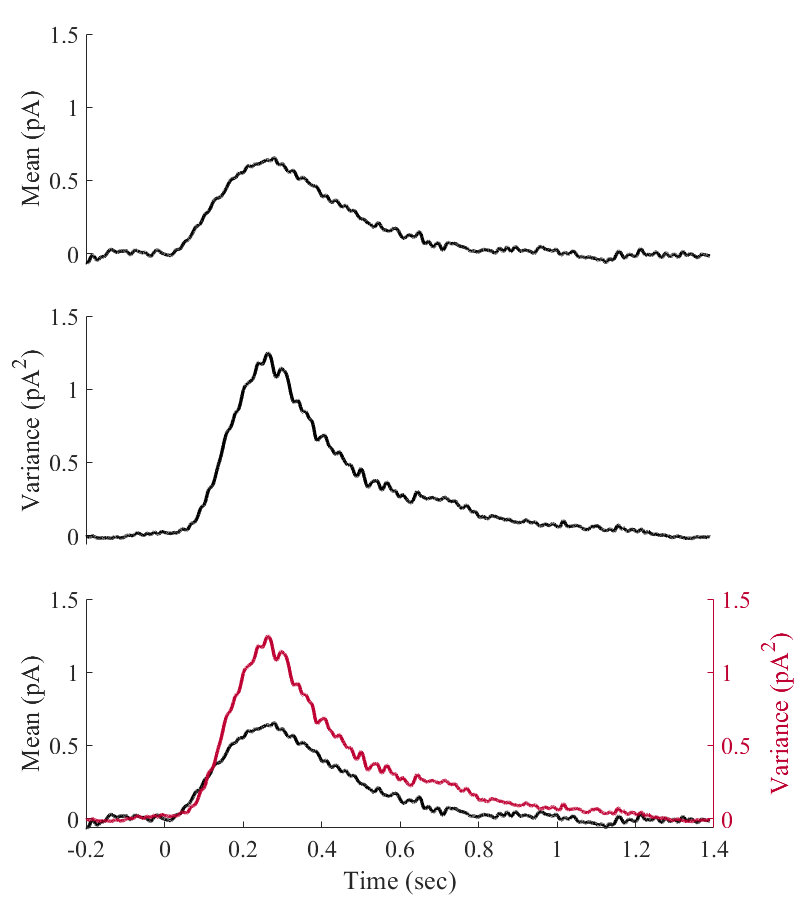

fig = figure('defaultaxesfontname','Times New Roman');
fig.Position(3:4) = [800,900];
layout = tiledlayout(3,1,'Padding','compact','TileSpacing','compact');
ax = gobjects(4,1);
ax(1) = nexttile(layout); % mean axes
ax(1).YLabel.String = sprintf("Mean (%s)",Units.Responses);

ax(2) = nexttile(layout); % variance axes
ax(2).YLabel.String = sprintf("Variance (%s^2)",Units.Responses);

ax(3) = nexttile(layout); % dual axes
ax(4) = axes(layout);
ax(4).Layout = ax(3).Layout;
ax(4).Color = 'none';
ax(4).YAxisLocation = 'right';

ax(3).YLabel.String = sprintf("Mean (%s)",Units.Responses);
ax(4).YLabel.String = sprintf("Variance (%s^2)",Units.Responses);
ax(4).YColor = [190, 0, 50]./255; % Crimson Glory
ax(4).XLabel.String = sprintf("Time (%s)", Units.Time);

set(ax,'FontSize',18);
set([ax(1:3).XAxis],'Visible', 'off');
% compute mean and var
responseMean = mean(groupedResponses,2,'omitnan');
responseVar = var(groupedResponses,0,2,'omitnan');

% subtract baselines
baselineIdx = time < 0;
responseMean = responseMean - mean(responseMean(baselineIdx));
responseVar = responseVar - mean(responseVar(baselineIdx));

% plot the lines
line(ax(1),time,responseMean,'color','k','linewidth',2.5);
line(ax(3),time,responseMean,'color','k','linewidth',2.5);
line(ax(2),time,responseVar,'color','k','linewidth',2.5);
line(ax(4),time,responseVar,'color',[190, 0, 50]./255,'linewidth',2.5);
linkaxes(ax,'xy');

## Calculating The Single-Photon Response Amplitude

According to [Baylor, Lamb, and Yau (1979)](https://physoc.onlinelibrary.wiley.com/doi/abs/10.1113/jphysiol.1979.sp012716), if we assume a poisson distribution of events, the ensemble variance should be related to the mean response and unit-amplitude by the relation:

#### $\sigma^2=\mu a$.

#### 
$$\mu=ma$$



$$\therefore m = \frac{\sigma^2}{a^2}$$


If we take the average variance and average mean response near the peak of the response, we can then compute the average single-photon response amplitude.

peakWindow = [0.23,0.29];
peakIdx = time > peakWindow(1) & time < peakWindow(2);

peakVar = mean(responseVar(peakIdx));
peakMean = mean(responseMean(peakIdx));

unitAmp = round(peakVar / peakMean,3,'significant');
fprintf('a = %3g pA\n',unitAmp);

a = 1.86 pA


aSquared = unitAmp^2;
m = round(peakVar/aSquared,2,'sig');
fprintf('m = %3g\n',m);

m = 0.34


## Amplitude Histogram

Generate the amplitude histogram.


$$r_j=r_j(T_2)-r_j(T_1)$$



$$\mu=\bar{r}(T_2)-\bar{r}(T_1)$$



$$a_j = \frac{\int_{T_3}\{r_j(t)-r_j(T_3)\}\{\bar{r}(t)-\bar{r}(T_3)\}\, dt}{\int_{T_3}\{\bar{r}(t)-\bar{r}(T_3)\}^2\, dt}$$



$$p( r) = \sum_{k=0}^{\infty}\frac{e^{-m}m^{k}}{k!}\frac{1}{(2\pi (\sigma_0^2 + k\sigma_1^2))^{1/2}}\exp(-\frac{(r-ka)^2}{2(\sigma_0^2 + k\sigma_1^2)})$$


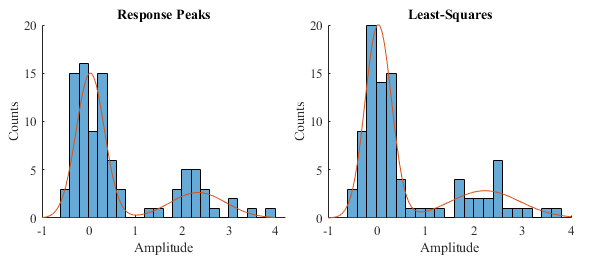

% from Baylor et al. eqn. 1
responsePeaks = mean(groupedResponses(peakIdx,:),1) - ...
  mean(groupedResponses(baselineIdx,:),1);

% from Baylor et al. eqn. 5
[offsets,amplitudes] = deal(zeros(nResp,1));

analysisDomain = [-0.2,0.8];
analysisIdx = time > analysisDomain(1) & time < analysisDomain(2);
nAnPts = sum(analysisIdx);

for r = 1:nResp
  b = [ones(nAnPts,1)/2,responseMean(analysisIdx)] \ groupedResponses(analysisIdx,r);
  offsets(r) = b(1);
  amplitudes(r) = b(2);
end

responseAmps = peakMean * amplitudes;

% Plot the amplitude histogram
fig2 = figure('defaultaxesfontname','Times New Roman');
fig2.Position(3:4) = [600,260];
layout = tiledlayout(fig2,1,2,'Padding','compact','TileSpacing','compact');
ax = gobjects(1,2);
for a = 1:2
  ax(a) = nexttile(layout);
  ax(a).NextPlot = 'add';
end

histogram(responsePeaks,'binwidth',0.2,'Parent',ax(1));
histogram(responseAmps,'binwidth',0.2,'Parent',ax(2));
set([ax.YLabel],'String',"Counts");
set([ax.XLabel],'String',"Amplitude");
ax(1).Title.String = 'Response Peaks';
ax(2).Title.String = 'Least-Squares';
% fit mixture of gaussians
gmodel = fitgmdist(responseAmps(:),2,'Replicates',1000);
gmodel2 = fitgmdist(responsePeaks(:),2,'Replicates',1000);

gpdf = gmodel.pdf(linspace(-1,4)');
plot(ax(2),linspace(-1,4),gpdf./max(gpdf).*20);
gpdf2 = gmodel2.pdf(linspace(-1,4)');
plot(ax(1),linspace(-1,4),gpdf2./max(gpdf2).*15);

gmodel2

gmodel2 = 
Gaussian mixture distribution with 2 components in 1 dimensions
Component 1:
Mixing proportion: 0.742530
Mean:   0.036047097678120
Component 2:
Mixing proportion: 0.257470
Mean:   2.343226789184264


squeeze(gmodel2.Sigma)

ans =    0.091319302785506
   0.355856931952589



gmodel

gmodel = 
Gaussian mixture distribution with 2 components in 1 dimensions
Component 1:
Mixing proportion: 0.729072
Mean:   0.035170615268470
Component 2:
Mixing proportion: 0.270928
Mean:   2.230981494374631


squeeze(gmodel.Sigma)

ans =    0.073545454419022
   0.511115737061316
